# **Input  Nanopore Sequencing Data (FASTQ file)**

info = fastqinfo('lambda_nanopore.fastq')

nfo = struct with fields:
           Filename: 'lambda_nanopore.fastq'
           FilePath: 'C:\Teaching\BMES 375-2020-summer-final\hw7sequencing_fastq_QC'
        FileModDate: '07-Apr-2020 14:41:00'
           FileSize: 10926131
    NumberOfEntries: 947


reads = fastqread('lambda_nanopore.fastq')

reads = 1×947 struct array with fields:
    Header
    Sequence
    Quality


## **Read Length Distribution of All Sequencing Reads**

seqs = {reads.Sequence} % covert it to a cell array

seqs = 1×947 cell array
  Columns 1 through 399

    {'GTTGTGTGCGCGCTG…'}    {'AGTATGCTTCGTTCA…'}    {'CACTAGGTCGCGCCC…'}    {'CGTGTACTTCGTTCA…'}    {'ACTCTATTAAGTGAA…'}    {'GACTCGTTTCAGCAG…'}    {'ATTGCTAGGTCGCCA…'}    {'GTTACTAAGCGGTTC…'}    {'ATGCTGTAAATTCCA…'}    {'CAGTATAATTGCTGT…'}    {'AGCTGAGCTAATCGT…'}    {'ACTATTGGGAAGTCA…'}    {'CTGTTTACTTCAGTT…'}    {'CATTCACTAGTTTCA…'}    {'CGGTACTTCGTTCCA…'}    {'GTTGTACTTCGTTCA…'}    {'GTATGCTTCGTTCGG…'}    {'ATTGCTGAGCTAATC…'}    {'CGGTGTACTATTGGG…'}    {'CACTTTATTGGGAAG…'}    {'CACTTTATTCATGTT…'}    {'GTTGTACTTCGTTCA…'}    {'CAGTATGTGATTCAT…'}    {'GTTGTACTTCGTTCA…'}    {'GTTGTATTGCTATTG…'}    {'GTTGTACGCCCCATT…'}    {'CGGTATGCTTCGTTC…'}    {'CGGTATGCCGTTCAG…'}    {'GGTGTACTTCGTTCC…'}    {'ACTGAGCTAATCGTT…'}    {'CACTCGTTTCAGCAG…'}    {'CAGTGTATTGCTGGG…'}    {'ACTGTAAATTCAGAG…'}    {'GGTATACTTCGTTCA…'}    {'CGATGTGCTTCGTTC…'}    {'GTTGTACTTCGTTCA…'}    {'GGTAGCTGCTTCGTT…'}    {'GATGTACTTCGTTCC…'}    {'ACTATTGGGAAGTCA…'}    {'CGATGTACT

% readsLen = cellfun(?); % use cellfun to calculate the read length.  https://www.mathworks.com/help/matlab/ref/cellfun.html

% figure(); 
% % plot the histogram of the read length.
% xlabel('Read Length'); ylabel('Number of Sequence Reads');
% title('Length distribution');
% % plot the average read length using the boxplot. ylabel('Average Read Length');


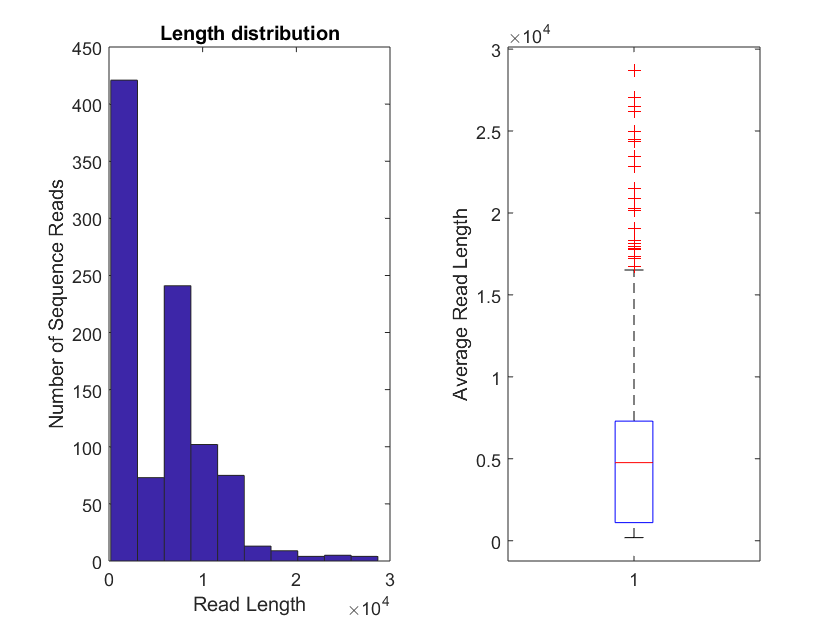

## **Quality Score Distribution per Sequencing Read**

sq = {reads.Quality}; % in ASCII format
% use cellfun() to convert the ASCII code to digits and -33. SQ = cellfun(? 'UniformOutput', false); 
sq{1,1}

ans = '/+++$$#$$&%'&+&,%'(+2%&&%.*)$)&$#%':==:2,60,,0)$$%/..,9:;'B'977644)&)*$/33&30435.23,'%)%(FDAJHOFBGOKLH?=CH@>?=1..8G<;HE;DF1$+65).%,,591,+:5<73<<))'((&&-DLLLID1;JI=AC7<5(BB,(&'-''/7===EA?89;><=<C=@<??B>N=89,$($1;E2GVN4-+/627&,%*;:>19::CI;C-3<>=%*21231*#%-1:7:%/$''(&''91>899F69?;;F@@BJA>0'#+))8-%4?9?>C=&71><FA=@<:8AB;>>9-(4+$$$'1B?B?A49=:8**0;>1424,,/*/7/9:880317=556>9+,++%%'(+%###'%-&(+.)(+'%5>=4+42-++%%$$0.5)::8;=,<*0*($'*6:>CA59.:4;,..31374*%.<2.--'+6,3(1682$($$%&(,,/246@E@75?610.6++;<23384BACFFDF:690333//+>@HF>>ECDA.*)2=>>=/#$###*('&)<>07())/2&&&(($'$9*3;:8C>AAD=A?C126,434=EA<:?>C0699<;*''ECD,AAC6?@IDD552%;7C5,,118577BD>/=6762%'-0:64;?@:%%%6<@EC;8;=@N[R/@BA4AB>1-(8:B97<:=:BM?8;GD0698+@;=C>+2229435209/24;<3,=')/:@N6//4E@F<:=:555:93-,9=<8:<=.06-./'#$%25;=4?'+<7633-')),378>=1<MJ@FDJK:=;;?,2C>82).-+#$&('25B>:;?(8&&@A<$4A>000'-/-./1%';6=3%)**-.$*:91&16<>8FCC@B;B4,)&+10)6;>6578>66:<@?@11+'3/;5.*)32;?B03/--6=9.433&1/2%%'(':?89-..691*E168=:@B9?PI?F>@-2?6585=445AC?;:AB:8CCCJ=:::*3>BDDK

`ans = ``1×6267`

`    14    10    10    10     3     3     2     3     3     5     4     6     5    10     5    11     4     6     7    10    17     4     5     5     4    13     9     8     3     8     5     3     2     4     6    25    28    28    25    17    11    21    15    11    11    15     8     3     3     4`

%=== average, median and standard deviation
% use cellfun to calculate the mean of the score of each read. avgSQ = cellfun(?);
% use cellfun to calculate the median of the score of each read. medSQ = cellfun(?);
% use cellfun to calculate the standard deviation of the score of each read. stdSQ = cellfun(?);

%=== plot distribution of median and average quality
% figure();
% % plot the histogram of the median score of every read;
% xlabel('Median Score SQ'); ylabel('Number of sequence reads');
% % use boxplot to plot the average score of every read;subplot(1,2,2); boxplot(?); ylabel('Average Score SQ');

## 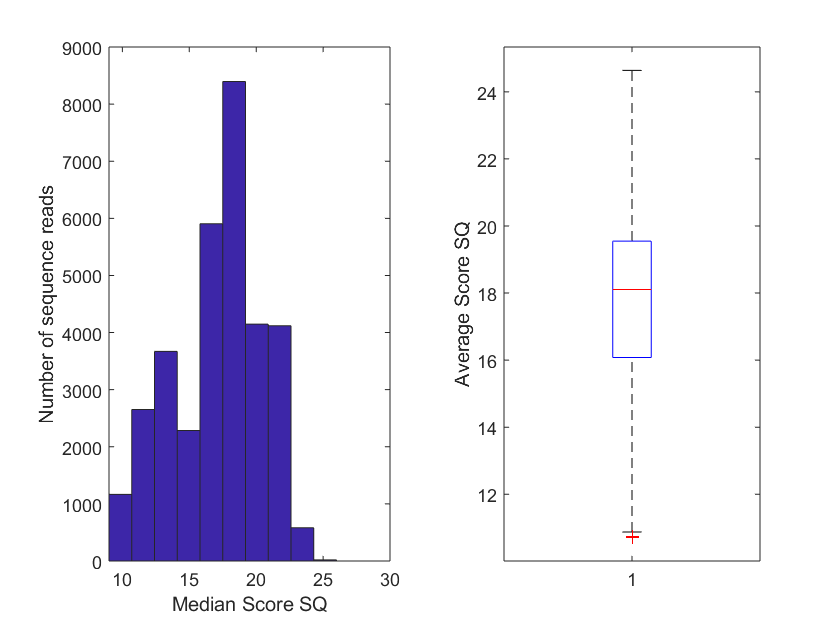

## GC Content Histogram per sequence read

test = seqs{1,2}; 
testg=strfind(test, 'G')

testg =      2     6    11    16    19    34    41    44    47    55    56    58    60    66    71    72    77    96    98    99   108   113   124   138   141   142   146   148   152   157   161   163   167   184   185   189   190   192   193   201   203   213   214   216   218   223   224   244   252   253


ng=numel(testg)  %how many G

ng = 2949


% use the cellfun  find the number of Gs for every read 
% ind_G = cellfun(?, 'UniformOutput', false);
% use the cellfun  find the number of Cs for every read 
% ind_C = cellfun(?, 'UniformOutput', false);
% use the cellfun  find the length for every read, the number of A,T,G,C.
% readL=cellfun(?, 'UniformOutput', false);
% calculate GC content total number of G and C/ read length 
% indGC=ind_G)+(ind_C); need to convert to matrix before adding
% GC=indGC/readL; convert to readl to matrix and be careful with matrix division and regular division
% figure(); 
% subplot(1,2,1);
% % histogram of GC content for every read ;
% xlabel('GC Content'); ylabel('Number of Sequence Reads');
% subplot(1,2,2);
% boxplot(GC); ylabel('Average GC Content');



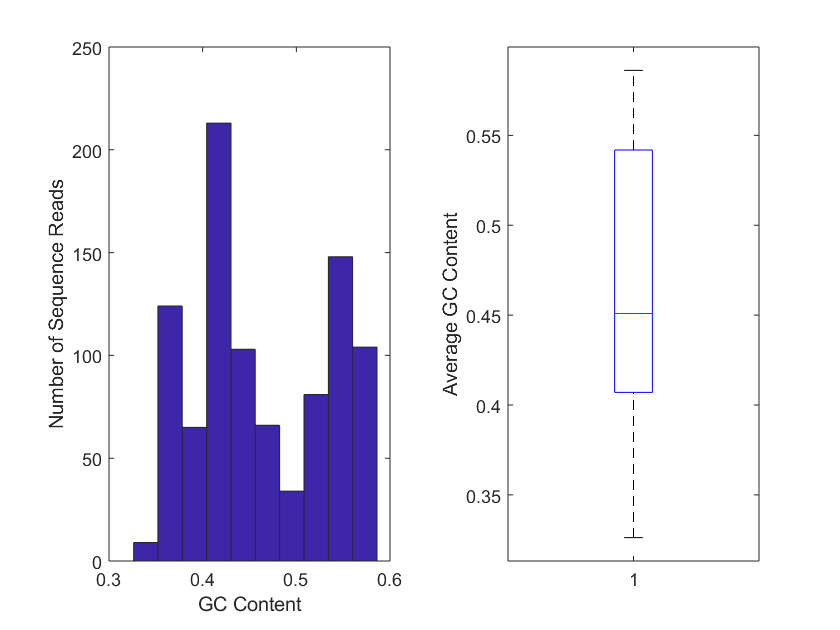

# **Input Illumina Sequencing Data (FASTQ file)**

## Read Length

reads_illum = fastqread('lambda_illum.fastq');
seqs_illum = {reads_illum.Sequence};
% caulate the readl length. readsLen_illum = cellfun(?); 

% figure(); subplot(1,2,1);hist(readsLen_illum);
% xlabel('Read Length'); ylabel('Number of Sequence Reads');
% title('Length distribution');
% subplot(1,2,2);boxplot(readsLen_illum); ylabel('Average Read Length');

## **Quality Score Distribution per Sequencing Read**

% sq_illum = {reads_illum.Quality}; % in ASCII format
% calculate the SQ of each base using cellfun. SQ_illum = cellfun(?, 'UniformOutput', false); 
% SQ_illum{1,1}

`ans = ``1×160`

`    34    34    34    34    34    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    38    37    38    38    38    38    38    37`

%=== average, median and standard deviation
% use cellfun to calculate the mean of the score of each read. avgSQ_illum = cellfun(?);
% use cellfun to calculate the median of the score of each read. medSQ_illum = cellfun(?);
% use cellfun to calculate the standard deviation of the score of each read. stdSQ_illum = cellfun(?);
% avgSQ_illum = cellfun(?);
% medSQ_illum = cellfun(?);
% stdSQ_illum = cellfun(?);

%=== plot distribution of median and average quality
% figure();
% subplot(1,2,1); hist(medSQ_illum);
% xlabel('Median Score SQ'); ylabel('Number of sequence reads');
% subplot(1,2,2); boxplot(avgSQ_illum); ylabel('Average Score SQ');

## GC Content Histogram per sequence read


% use the cellfun  find the number of Gs for every read 
% ind_G_illum  = cellfun(?, 'UniformOutput', false);
% use the cellfun  find the number of Cs for every read 
% ind_C_illum  = cellfun(?, 'UniformOutput', false);
% use the cellfun  find the length for every read, the number of A,T,G,C.
% readL_illum =cellfun(?, 'UniformOutput', false);
% calculate GC content total number of G and C/ read length 
% indGC_illum =ind_G_illum )+(ind_C_illum ); need to convert to matrix before adding
% GC_illum =indGC_illum /readL_illum ; convert to readl to matrix and be careful with matrix division and regular division
% figure(); 
% subplot(1,2,1);
% % histogram of GC content for every read ;
% xlabel('GC Content'); ylabel('Number of Sequence Reads');
% subplot(1,2,2); 
% % boxplot(?);ylabel('Average GC Content')


# **List the Two Main Differences Between IIIumina Read and Nanopore Data**

**First difference:  Plot the nanopore and llIumina data together using histogram and box plot (caption and conclusion)**

**Second difference: Plot the nanopore and Illumina data together using histogram and box plot (caption and conclusion)**

# **Call seqqcplot() on Illumina data**

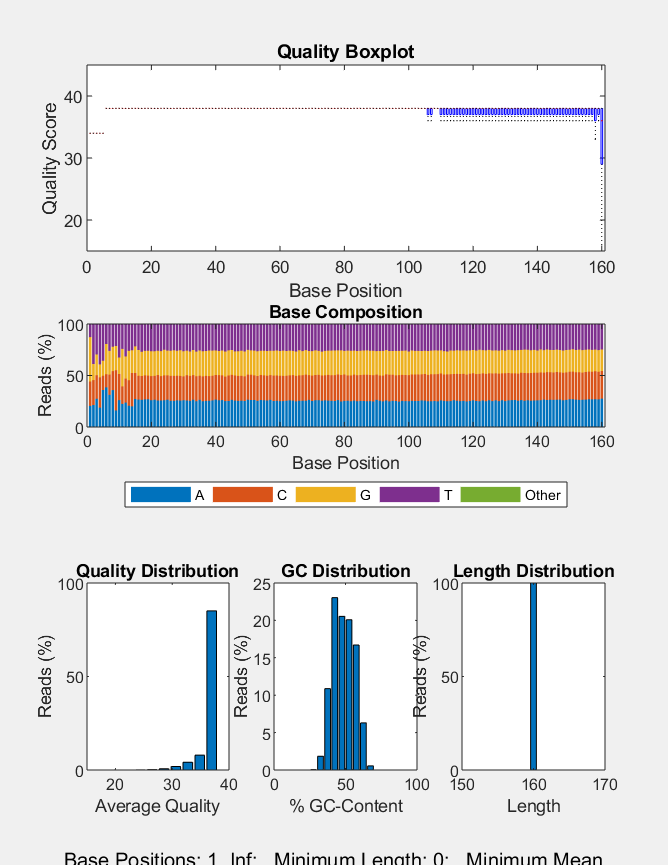

ans =   Figure (SummaryFigure) with properties:

      Number: 1
        Name: 'lambda_illum.fastq'
       Color: [0.9400 0.9400 0.9400]
    Position: [418.3333 61.6667 445.3333 576.6667]
       Units: 'pixels'

  Show all properties


seqqcplot('lambda_illum.fastq')

% seqqcplot('lambda_nanopore.fastq')  what happens and why?

# **Filter Sequencing Reads**

[outFile1,in,out] = seqfilter('lambda_nanopore.fastq','Method','MeanQuality','Threshold',15)

outFile1 = 1×1 cell array
    {'C:\Teaching\BMES 375-2020-summer-final\hw7sequencing_fastq_QC\lambda_nanopore_filtered.fastq'}


in = 797

out = 150